# Program to Determine and Plot the Coordinates of Atoms in a Face Centered Cubic System

### MEPC18 - Engineering Materials Programming Assignment

**Name:** Guru Vishnu M            

**Roll Number:** 111120050

## **Input Variables **

Radius of the atom (r) and length (l), breadth (b), and height (h) of the space that needs to be filled with face centered cubic structures (FCC):

r = sqrt(2);
l = 10;
b = 15;
h = 20;

## Calculations

Determination of the side length (a) of the unit cell and the number of unit cells along each principal directions of the cuboidal space (nx, ny, and nz):

a = 2 * sqrt(2) * r;

nx = floor(l/a);
ny = floor(b/a);
nz = floor(h/a);

If the cuboidal space that needs to be filled is insufficient even for a single unit cell, i.e., if either one of nx, ny, or nz which denote the numbers of unit cells along the principal directions is zero, the following code segment displays that the space is insufficient and terminates the program:

if nx == 0 || ny == 0 || nz == 0
    disp("Insufficient Space")
    return 
end

Following segment shows the variable naming convention for two layers as seen from the top. Atoms laelled 'A' are present at the corners of the unit cells, 'B' at the face centre of the planes parallel to the xy plane, 'C' at the face centres of planes parallel to the xz plane, and 'D' at face centres of planes parallel to the yz plane. A and B are in the same layer (i.e., have same values of z coordinates) and so do C and D. But A and B, and C and D are in different layers, each adjacent AB-CD layers separated by a distance of a/2:

% A D A D A D A
% C B C B C B C
% A D A D A D A
% C B C B C B C 
% A D A D A D A
% C B C B C B C
% A D A D A D A 
% 
% (3 unit cells in x direction x 3 unit cells in y direction)

In the following section, w is an array consisting of the distances of each atom along one of the principal directions along the origin. This is used further to calculate the x and y coordinates of the atoms in one layer and store it in a nx + 1 by ny + 1 matrices Ax and Ay:

w = 0 : a : max([nx, ny, nz]) * a;

Ax = ones(nx + 1, ny + 1);
Ay = ones(nx + 1, ny + 1);

Ax = Ax .* w(1:nx+1)';
Ay = Ay .* w(1:ny+1);

From the crystal structure shown above, it is evident that atoms labelled 'B' are shifted by distance a/2 along both the x and y axes from atoms labelled 'A'. And, the number of 'B' atoms is one less than the number of 'A' atoms along each direction. Thus, Bx and By can be determined as follows:

Bx = Ax(1:nx, 1:ny) + a/2;
By = Ay(1:nx, 1:ny) + a/2;

Similarly, the x and y coordinates of atoms labelled 'C' and 'D' can be calculated:

Cx = Ax(1:nx, :) + a/2;
Cy = Ay(1:nx, :);

Dx = Ax(:, 1:ny);
Dy = Ay(:, 1:ny) + a/2;

Now, we have calculated the x and y coordinates of atoms in layer 1 (consisting of A and B), and layer 2 (consisting of C and D). Next, we need to move to the third dimesion. The z coordinates of layer 1 will be same as that of vector w. For layer 2, the z coordinates will be the vector w(2:nz+1)/2.

A = ones((nx + 1) * (ny + 1) * (nz + 1), 3);
for z = 1 : nz + 1
    A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 1) = A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 1) .* Ax(:);
    A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 2) = A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 2) .* Ay(:);
    A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 3) = A(1 + (z - 1) * ((nx + 1) * (ny + 1)) : z * ((nx + 1) * (ny + 1)), 3) * w(z);
end

B = ones(nx * ny * (nz + 1), 3);
for z = 1 : nz + 1
    B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 1) = B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 1) .* Bx(:);
    B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 2) = B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 2) .* By(:);
    B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 3) = B(1 + (z - 1) * (nx * ny) : z * (nx * ny), 3) * w(z);
end

C = ones(nx * (ny + 1) * nz, 3);
for z = 1 : nz
    C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 1) = C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 1) .* Cx(:);
    C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 2) = C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 2) .* Cy(:);
    C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 3) = C(1 + (z - 1) * (nx * (ny + 1)) : z * (nx * (ny + 1)), 3) * w(z) + a/2;
end

D = ones((nx + 1) * ny * nz, 3);
for z = 1 : nz
    D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 1) = D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 1) .* Dx(:);
    D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 2) = D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 2) .* Dy(:);
    D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 3) = D(1 + (z - 1) * ((nx + 1) * ny) : z * ((nx + 1) * ny), 3) * w(z) + a/2;
end

## Plotting Unit Cells

### Code Segment to Plot the Coordinates of Atoms

p1 = plot3(A(:,1), A(:,2), A(:, 3), 'o', color = [1 0 0]);
p1.MarkerFaceColor = [1 0 0];

axis equal;
hold on;

p2 = plot3(B(:,1), B(:,2), B(:, 3), 'o', color = [0 1 0]);
p2.MarkerFaceColor = [0 1 0];

p3 = plot3(C(:,1), C(:,2), C(:, 3), 'o', color = [0 1 0]);
p3.MarkerFaceColor = [0 1 0];

p4 = plot3(D(:,1), D(:,2), D(:, 3), 'o', color = [0 1 0]);
p4.MarkerFaceColor = [0 1 0];

### Code Segment to Display Edges of Unit Cells

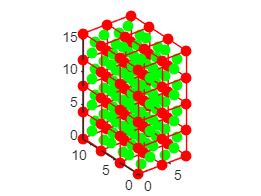

for z = 0 : nz
    for x = 0 : nx
        plot3([(x * a) (x * a)], [0 (ny * a)], [(z * a) (z * a)], color = [1 0 0]);
    end
    for y = 0 : ny
        plot3([(nx * a) 0], [(y * a) (y * a)], [(z * a) (z * a)], color = [1 0 0]);
    end
end

for x = 0 : nx
    for y = 0 : ny
        plot3([(x * a) (x * a)], [(y * a) (y * a)], [0 (nz * a)], color = [1 0 0]);
    end
end

% xlabel("Length")
% ylabel("Breadth")
% zlabel("Height")

hold off;

## Statistics

n = nx * ny * nz                    % Number of Unit Cells

n = 24

s = round(l * b * h - n * a^3, 10)  % Space which is unfilled

s = 1464

## Exporting Coordinates as a CSV File

Output = [A; B; C; D];
writematrix(Output, 'FCC_Coordinates.csv');